addpath(genpath('/datascience/projects/statisticallyfit/github/MATLAB/MatlabTutorial/AMTH250_NumericalMatlab/Numerical Analysis/Interpolation'))

Question 1: write the linearinterpolation function. 

xs = 1:11;
ys = [850 798 818 903 1026 1042 1022 1069 1070 1135 1096];

splines = linearSpline(xs, ys)

$$splines = \left(\begin{array}{c} 902-52\,x\\ 20\,x+758\\ 85\,x+563\\ 123\,x+411\\ 16\,x+946\\ 1162-20\,x\\ 47\,x+693\\ x+1061\\ 65\,x+485\\ 1525-39\,x \end{array}\right)$$

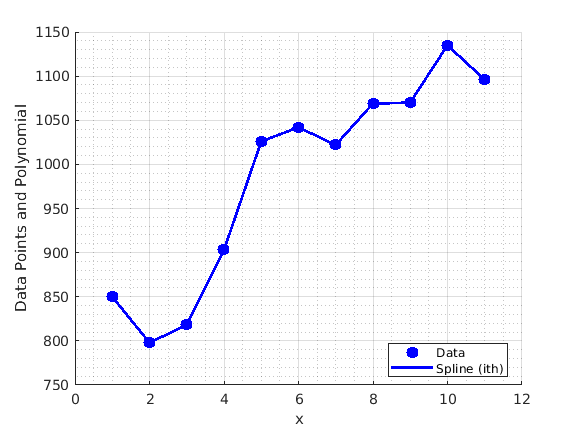

plotSplines(xs, ys, splines)

% estimations
syms x; 
linearinterp = @(xx) subs(splines, x, xx)

linearinterp = function_handle with value:
    @(xx)subs(splines,x,xx)



% evaluate with sample xx
yy = linearinterp(1:0.1:11) % the sample interpolated values

% estimate
y1=calcSpline(xs, splines, 3.5)

$$y1 = \frac{1721}{2}$$

y2 = calcSpline(xs, splines, 7.7)

$$y2 = \frac{10549}{10}$$

y3 = calcSpline(xs, splines, 10.1)

$$y3 = \frac{11311}{10}$$

% NOW: plotting the interpolated values above to ensure that they do indeed lie on the straight line segments. 

% making range for plotting the interpolated polynomial
syms x; 
n = length(xData);

figure(1); clf; hold on; grid on; grid minor;

% plot data points
plot(xData, yData, 'b.', 'MarkerSize', 30);

for i = 1:n-1
    % getting calculated values of the ith spline poly in the interval of 
    % x(i), x(i+1)
    xx = xData(i): 0.01: xData(i+1);
    ss = subs(splinePolys(i), x, xx);
    
    %plotting
    plot(xx, ss, 'b-', 'LineWidth', 2)
end

% add x-axis
%plot([min(xData), max(xData)], [0 0]);

xlabel('x')
ylabel('Data Points and Polynomial')

legend('Data', 'Spline (ith)', 'Location', 'Best')